## Manipulator Rigid Body Model

Create a rigid body definition for manipulator with 3 DOF. 

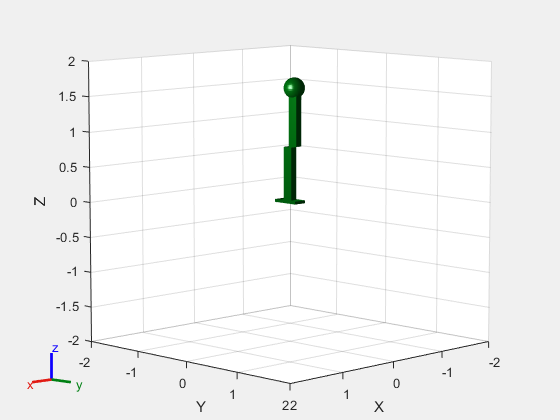

robotarm = rigidBodyTree("DataFormat","column");
base = robotarm.Base;

% Body
platform = rigidBody("base_platform");
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
gripper = rigidBody("gripper");

ManipulatorArm.Base.dim = [.2,.4,.04];
ManipulatorArm.Arm1.dim = [0.1,0.15,0.75];
ManipulatorArm.Arm2.dim = [0.1,0.15,0.75];
ManipulatorArm.Grip.dim = [.3,.1,.1];


% Collision
collBase = collisionBox(.2,.4,.04); % box: length, width, height (x,y,z)
collBase.Pose = trvec2tform([0 0 0.04/2]);
coll1 = collisionBox(0.1,0.15,0.75); % box: length, width, height (x,y,z)
coll1.Pose = trvec2tform([0 0 0.75/2]);
coll2 = collisionBox(0.1,0.15,0.75); % box: length, width, height (x,y,z)
coll2.Pose = trvec2tform([0 0 0.75/2]);
collGripper = collisionSphere(0.15); % sphere: radius
collGripper.Pose = trvec2tform([0 -0.015 0.15/2]);

addCollision(platform,collBase)
addCollision(arm1,coll1)
addCollision(arm2,coll2)
addCollision(gripper,collGripper)

% Attach Joints
jntBase = rigidBodyJoint("base_joint","fixed");
jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jntGripper = rigidBodyJoint("gripper_joint","revolute");

jnt1.JointAxis = [1 0 0]; % x-axis
jnt2.JointAxis = [1 0 0];
jntGripper.JointAxis = [0 0 1]; % z-axis

% Set offset positions for joints (add offsets on x to avoid collisions)
setFixedTransform(jnt1,trvec2tform([0 0 0.04]))
setFixedTransform(jnt2,trvec2tform([-0.1 0 0.75]))
setFixedTransform(jntGripper,trvec2tform([0 0 0.75]))

% Assemble
bodies = {base,platform,arm1,arm2,gripper};
joints = {[],jntBase,jnt1,jnt2,jntGripper};

figure("Name","Assemble Robot","Visible","on")
for i = 2:length(bodies) % Skip base. Iterate through adding bodies and joints.
            bodies{i}.Joint = joints{i};
            addBody(robotarm,bodies{i},bodies{i-1}.Name)
            show(robotarm,"Collisions","on","Frames","off");
            drawnow;
end


showdetails(robotarm)

--------------------
Robot: (4 bodies)

 Idx            Body Name           Joint Name           Joint Type            Parent Name(Idx)   Children Name(s)
 ---            ---------           ----------           ----------            ----------------   ----------------
   1        base_platform           base_joint                fixed                     base(0)   arm1(2)  
   2                 arm1                 jnt1             revolute            base_platform(1)   arm2(3)  
   3                 arm2                 jnt2             revolute                     arm1(2)   gripper(4)  
   4              gripper        gripper_joint             revolute                     arm2(3)   
--------------------


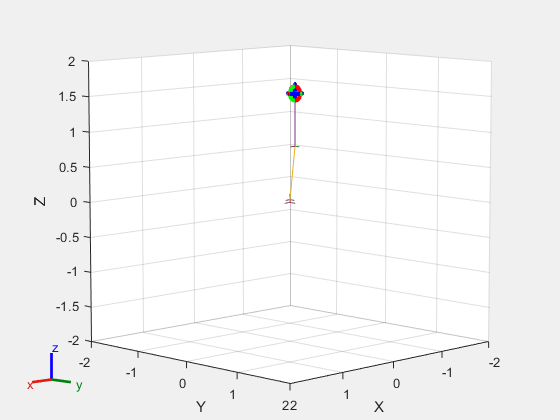


% Interactive
figure("Name","Interactive GUI")
gui = interactiveRigidBodyTree(robotarm,"MarkerScaleFactor",0.5);

## Trajectory


numWaypoints = 5;
q0 = homeConfiguration(robotarm);
qWaypoints = repmat(q0, numWaypoints, 1);

gik = generalizedInverseKinematics('RigidBodyTree', robotarm, ...
    'ConstraintInputs', {'cartesian','position','aiming','orientation','joint'})


## Simscape

robotSM = smimport(robotarm,ModelName="UnderwaterManipulator1");
model = get_param(robotSM,"Name");

mdlWks = get_param(robotSM,'ModelWorkspace');
assignin(mdlWks,"robotToTest",robotarm)
assignin(mdlWks,"q0",robotarm.homeConfiguration)
assignin(mdlWks,"dq0",zeros(size(robotarm.homeConfiguration)))

Arm = importrobot("UnderwaterArm.slx");
Arm.DataFormat = 'column';

ax = show(Arm)

ax =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


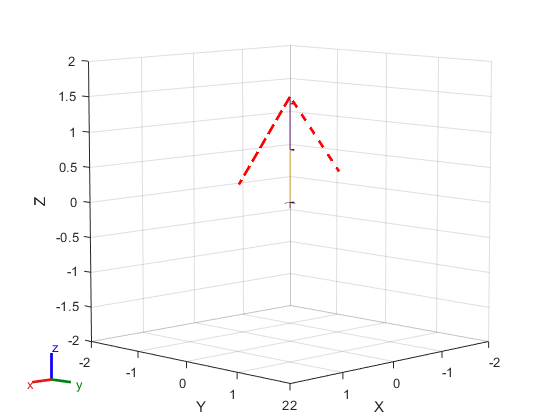

num_points = 4;
x = [0,1,0,-1];
y = [0,0,0,0];
z = [1.5,.35,1.5,.35];

hold on
plot3(x,y,z,'--r','LineWidth',2,'Parent',ax)
hold off

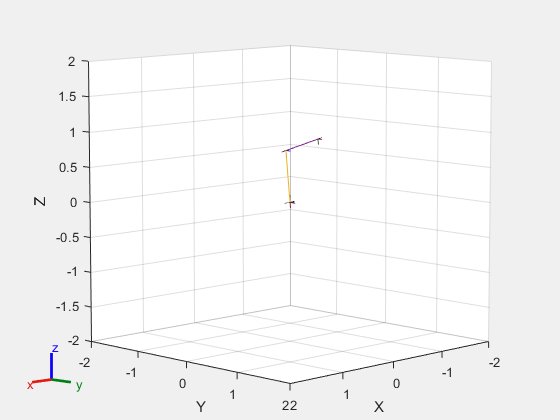

figure('Visible','on');
tformIndex = 1;
for i = 1:10:numel(out.configs.Data)/7
    currConfig = out.configs.Data(:,1,i);
    show(Arm,currConfig);
    drawnow
    
    xyz(tformIndex,:) = tform2trvec(getTransform(Arm,currConfig,'Body4'));
    tformIndex = tformIndex + 1;
end

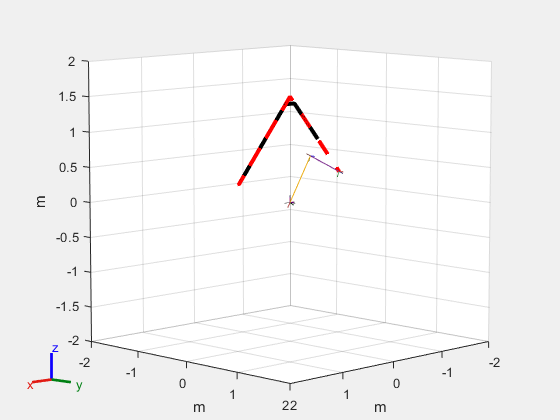

figure('Visible','on')
show(Arm,out.configs.Data(:,1,end));
 
hold on
plot3(xyz(:,1),xyz(:,2),xyz(:,3),'-k','LineWidth',3);
plot3(x,y,z,'--r','LineWidth',3)
xlabel('m')
ylabel('m')
zlabel('m')
hold off

Arm = importrobot("UnderwaterArm.slx");
Arm.DataFormat = 'column';

ax = show(Arm)

ax =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



num_points = 3;
x = [0,.1,0];
y = [0,0,0];
z = [1.4,.5,.1];

hold on
plot3(x,y,z,'--r','LineWidth',2,'Parent',ax)
hold off

close
open_system("InverseKinematics")
sim("InverseKinematics.slx")

ans =   Simulink.SimulationOutput:

                configs: [1x1 timeseries] 
                   info: [1x1 struct] 
                   tout: [3001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


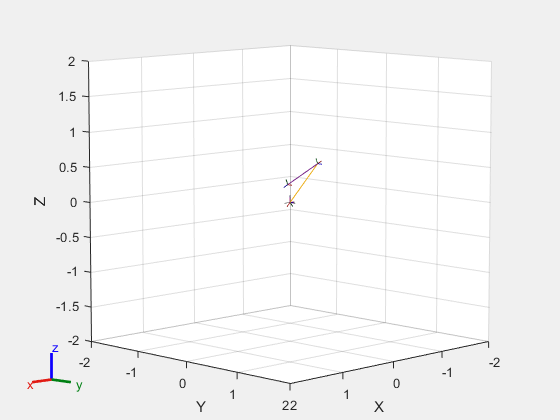


figure('Visible','on');
tformIndex = 1;
for i = 1:10:numel(out.configs.Data)/7
    currConfig = out.configs.Data(:,1,i);
    show(Arm,currConfig);
    drawnow
    
    xyz(tformIndex,:) = tform2trvec(getTransform(Arm,currConfig,'Body4'));
    tformIndex = tformIndex + 1;
end

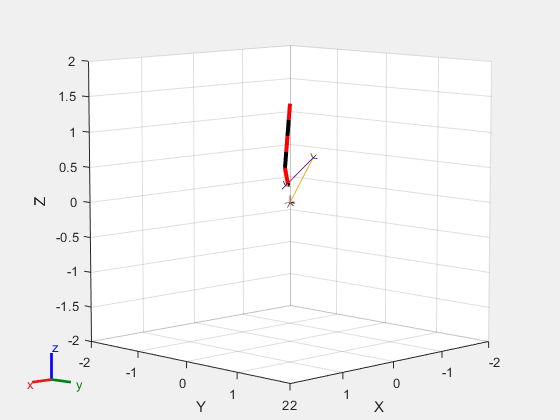


figure('Visible','on')
show(Arm,out.configs.Data(:,1,end));
 
hold on
plot3(xyz(:,1),xyz(:,2),xyz(:,3),'-k','LineWidth',3);
plot3(x,y,z,'--r','LineWidth',3)
hold off